# ECEN 611 Homework 1

`Shuxuan Chen | UIN: 132006082 | Fall 2024 `

clearvars 
clc

## Energy Stored in Magnetic Field 

% syms lambda i 
% Wfld = int(i,lambda,[0 lambda],'Hold',true)

## Exercise 1 

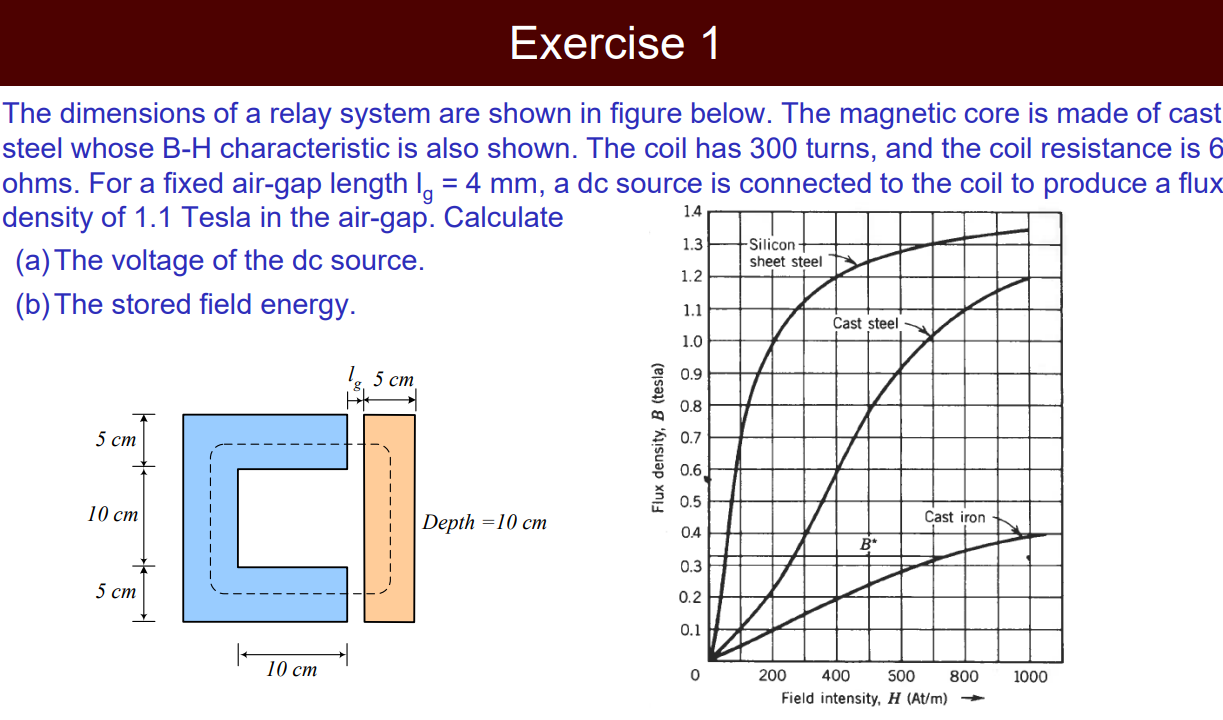

N = 300;   % number of turns of coil 
Rcoil = 6; % coil total resistance [ohms]
lg = 4e-3; % airgap length [m] 
Bg = 1.1;  % airgap flux density [T]
Depth = 10e-2; % [m]

uo = 4*pi*1e-7; % H/m
ug = uo;
Ag = 5e-2 * Depth % airgap cross-sectional area [m^2]

Ag = 0.0050

Ai = Ag;   % steel cross-sectional area facing airgap

### (a) DC Voltage Source 

B --> Φ --> H --> i --> V

Flux is the "currency" that holds constant across the steel and the airgap. Use this nature to obtain the flux density in the steel. 

fluxg = Bg * Ag;  % flux in the airgap  
fluxi = fluxg;    % flux in the steel 

Bi = fluxi / Ai  % steel flux density 

Bi = 1.1000

Read Hi corresponding to Bi from the characteristic 

% Read from B-H characteristic
Hi = 800; % [A·turns/m]

Permeability of steel can hence be calculated 

ui = Bi / Hi

ui = 0.0014

Construct flux paths and calculate relunctances for steel and airgap segments, respectively 

%%%%%%%%%%%%%% cm %%%%%%%%%%%%%%  
lccore_max = (5+10+5) + (5+10) + (5+10);
lccore_min = 10 + 10 + 10;
lccore_avg = (lccore_max + lccore_min) / 2;

licore_max = 5 + 5 + 10 + 5 + 5;
licore_min = 10;
licore_avg = (licore_max + licore_min) / 2;

%%%%%%%%%%%%%% m %%%%%%%%%%%%%% 
li = (lccore_avg + licore_avg) * 1e-2;
Ri = li / (ui*Ai)

Ri = 8.7273e+04

Rg = 2*lg / (ug*Ag)

Rg = 1.2732e+06

Use Ohm's law in both magnetic and electric fields to calculate current and hence voltage  

% fluxi = fluxg = flux 
icoil = (Ri+Rg)*fluxi / N    % [A] 

icoil = 24.9427

VDC = icoil * Rcoil           % [V] 

VDC = 149.6563

### (b) Stored Field Energy 

L = N^2 / (Ri+Rg);
Wfld = 1/2 * L * icoil^2 % [J]

Wfld = 20.5777

% use more general method instead (safer!)

## Exercise 2

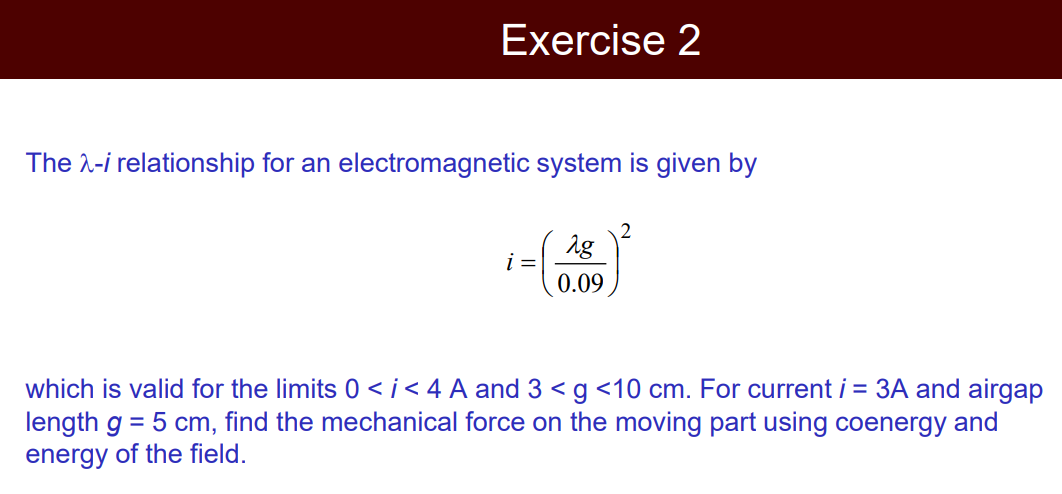

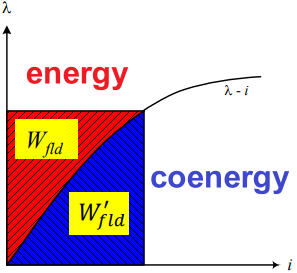

The problem statement asks for a snapshot of the force under a specific circumstance dictated by the current and airgap length. This is calculated from the perspectives of energy and coenergy and the results match. 

thisCurrent = 3;
thisAirGap = 5e-2;

syms i lambda g positive 
% assume( (i>0) && (i<4) )
assume( 3e-2 < g < 10e-2 )
currentFun = (lambda*g/0.09)^2

$$currentFun = \frac{10000\,g^{2}\,\lambda^{2}}{81}$$

expr = i == (lambda*g/0.09)^2;
lambdaFun(i,g) = solve(expr,lambda)

$$lambdaFun(i, g) = \frac{9\,\sqrt{i}}{100\,g}$$

thisLambda = lambdaFun(thisCurrent,thisAirGap)

$$thisLambda = \frac{9\,\sqrt{3}}{5}$$

### Determination of Force from Energy 

energyFun(g,lambda) = int(currentFun,lambda)

$$energyFun(g, lambda) = \frac{10000\,g^{2}\,\lambda^{3}}{243}$$

forceFun(g,lambda) = -diff(energyFun,g)

$$forceFun(g, lambda) = -\frac{20000\,g\,\lambda^{3}}{243}$$

force = double(forceFun(thisAirGap,thisLambda))

force = -124.7077

### Determination of Force from Coenergy 

coenergyFun = int(lambdaFun,i)

$$coenergyFun(i, g) = \frac{3\,i^{3/2}}{50\,g}$$

forceFun = diff(coenergyFun,g)

$$forceFun(i, g) = -\frac{3\,i^{3/2}}{50\,g^{2}}$$

force = double(forceFun(thisCurrent,thisAirGap))

force = -124.7077

***Q: In this case, forces obtained from energy and coenergy are the same. However, in Exercise 4 and 5, they differ in polarity. Why?***

## Exercise 3 

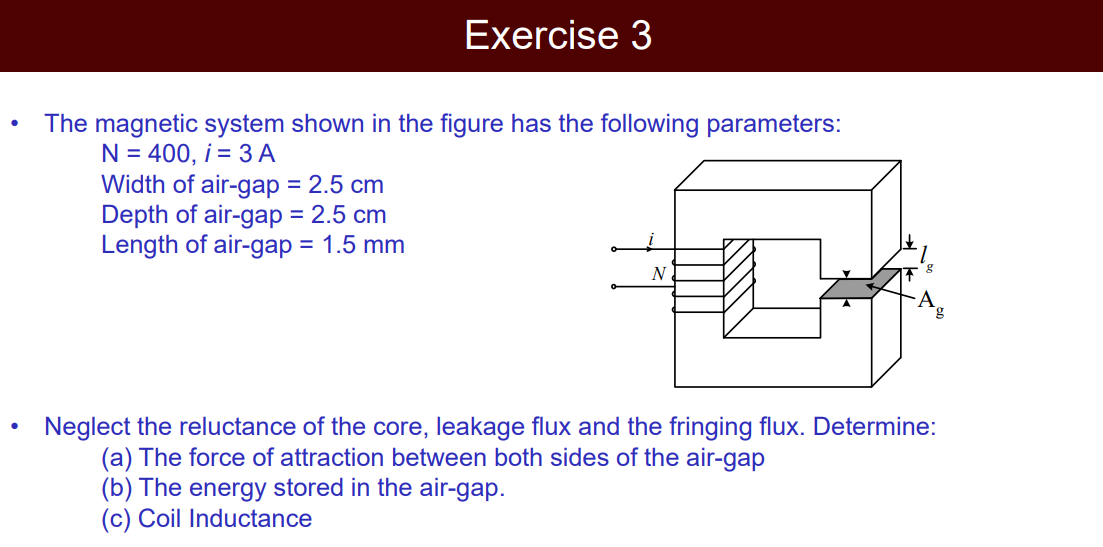

N = 400; 
i = 3;
Width = 2.5e-2;  % cm --> m 
Depth = 2.5e-2;  % cm --> m 
lg = 1.5e-3; % mm --> m

MMF = N*i;
H = MMF / lg

H = 800000

% Neglect the reluctance of the core, leakage flux and the fringing flux
% H drops only across the air gap  
Ag = Width * Depth

Ag = 6.2500e-04

Rg = lg / (ug*Ag)

Rg = 1.9099e+06

flux = MMF / Rg 

flux = 6.2832e-04

Bg = flux / Ag

Bg = 1.0053

lambda = N*flux

lambda = 0.2513

% lambda-i relationship: linear 
% k = lambda / i

### (a) Coil Inductance

L = lambda / i % [H]

L = 0.0838

### (b) Energy stored in the air-gap

Wfld = 1/2 * Bg^2/uo * Ag * lg

Wfld = 0.3770

### (c) Force of attraction between both sides of the air-gap

% Wfld = 1/2 * L * i^2 % [J]
force = -Wfld / lg

force = -251.3274

syms g 
RgFun = g/(ug*Ag);
Lfun = vpa(N^2/RgFun,4);
forceFun(g) = 1/2 * diff(Lfun,g) * i^2;
force = forceFun(lg)

$$force = -251.3$$

## Exercise 4 

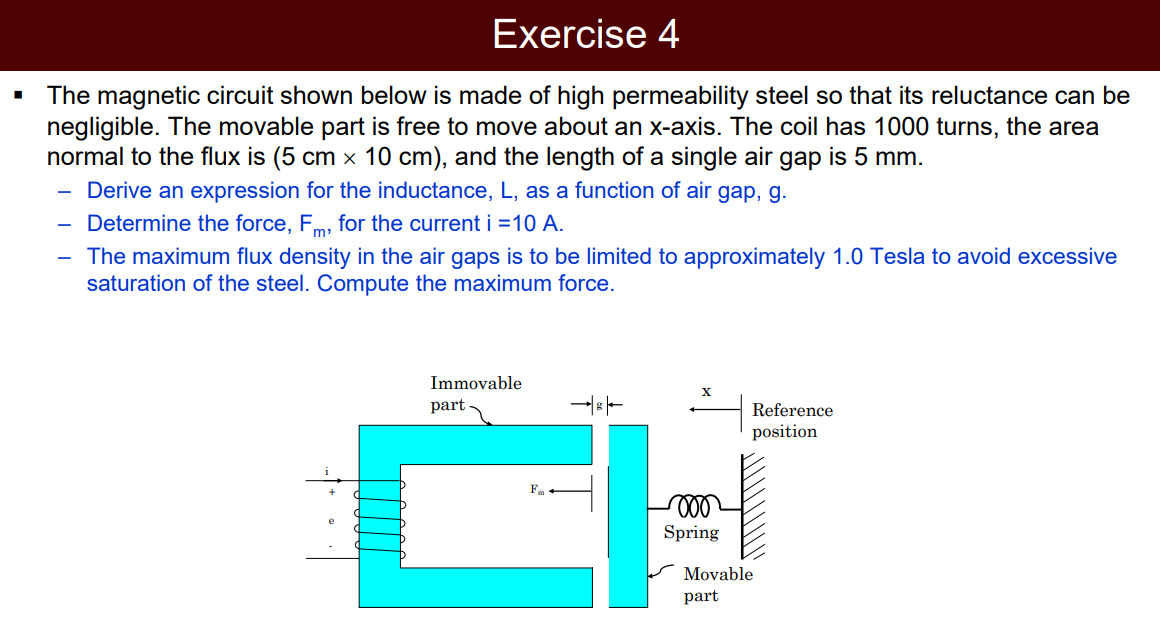

### (a) Inductance L = f(g)

% ui/uo > 1e3 ==> ui >> uo ==> H drops only in airgap 
N = 1000;
A = (5*10) * 1e-4;
thisAirGap = 5e-3;

syms i g K positive 
syms Rg(g) 
Rg(g) = 2*g/(uo*A);

digits(4)
Lfun = vpa(N^2/Rg)

$$Lfun(g) = \frac{0.003142}{g}$$

### (b) Mechanical Force Fm

% i = 10;
% MMF = N*i;
% H = MMF/g;

% Determination of Force from Coenergy 
% K*x from the spring side 
coenergyFun(i,g) = 1/2 * Lfun * i^2

$$coenergyFun(i, g) = \frac{0.001571\,i^{2}}{g}$$

forceFun = diff(coenergyFun,g)

$$forceFun(i, g) = -\frac{0.001571\,i^{2}}{g^{2}}$$

thisCurrent = 10;
force = forceFun(thisCurrent,thisAirGap)

$$force = -6283.0$$

### (c) Maximum Force before Saturation

Bsat = 1;
fluxsat = Bsat * A;
% R*flux = Ni
isat = vpa(Rg(thisAirGap)*fluxsat/N)

$$isat = 7.958$$

maxForce = forceFun(isat,thisAirGap)

$$maxForce = -3979.0$$

## Exercise 5 

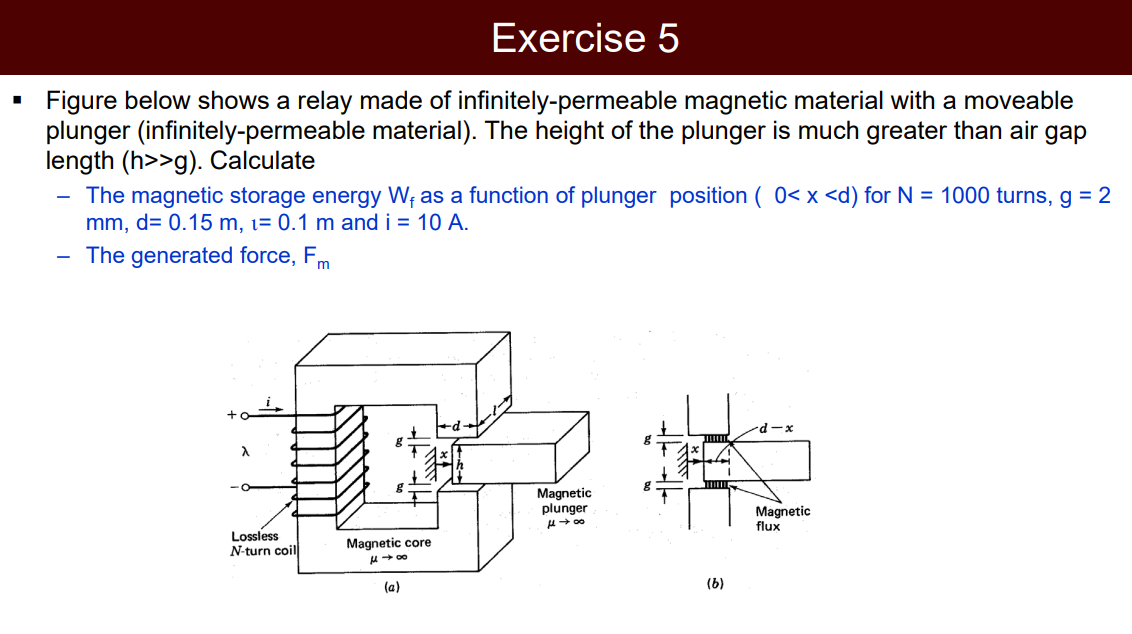

### (a) Stored Magnetic Energy Wf = f(plunger position x)

% clear Rg g 
N = 1000;
g = 2e-3;
d = 0.15;
l = 0.1;
i = 10;

syms x positive 
Ag = (d-x)*l;
% no flux directly travels through the airgap 
% without passing the plunger 

Rg = vpa(2*g/(ug*Ag));
L = N^2 / Rg;
MMF = N*i;
flux = MMF/Rg;
lambda = N*flux;
coenergyFun(x) = 1/2 * L * i^2

$$coenergyFun(x) = 235.6-1571.0\,x$$

Wf(x) = i*lambda - coenergyFun

$$Wf(x) = 235.6-1571.0\,x$$

### (b) Generated Force 

Fm = -diff(Wf,x)

$$Fm(x) = 1571.0$$

Fm = diff(coenergyFun,x)

$$Fm(x) = -1571.0$$

## Exercise 6

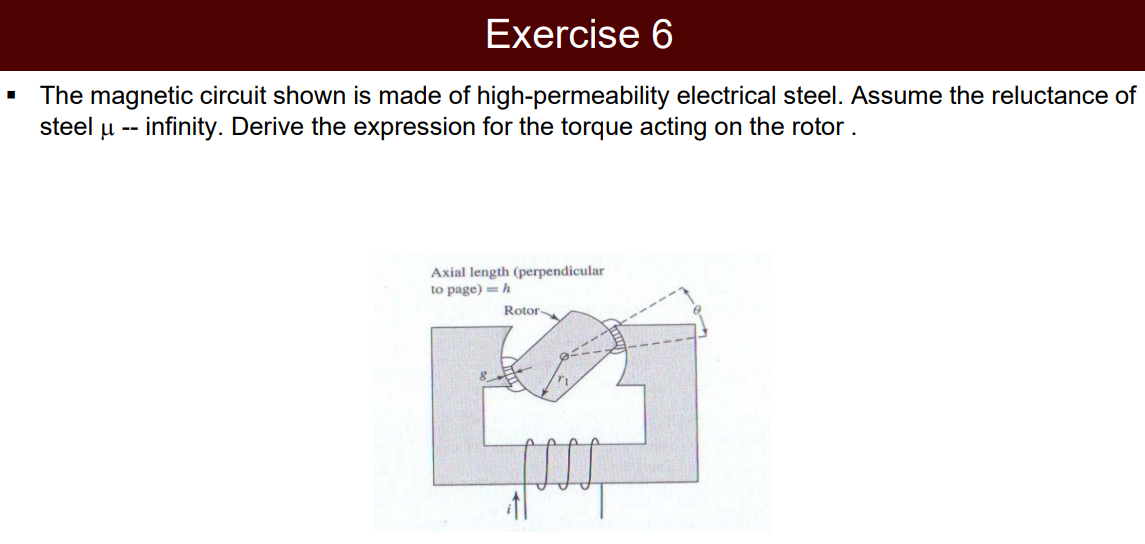

syms N i g h theta r_1
r1 = r_1;

MMF = N*i;
Ag = r1 * theta * h;
Rg = 2*g/(uo*Ag);
flux = vpa( MMF/Rg ); 
lambdaFun = N*flux;
coenergyFun = int(lambdaFun,i);
T = diff(coenergyFun,theta)

$$T = \frac{3.142e-7\,N^{2}\,h\,i^{2}\,r_{1}}{g}$$

***Q: Different coefficient ***

## Exercise 7

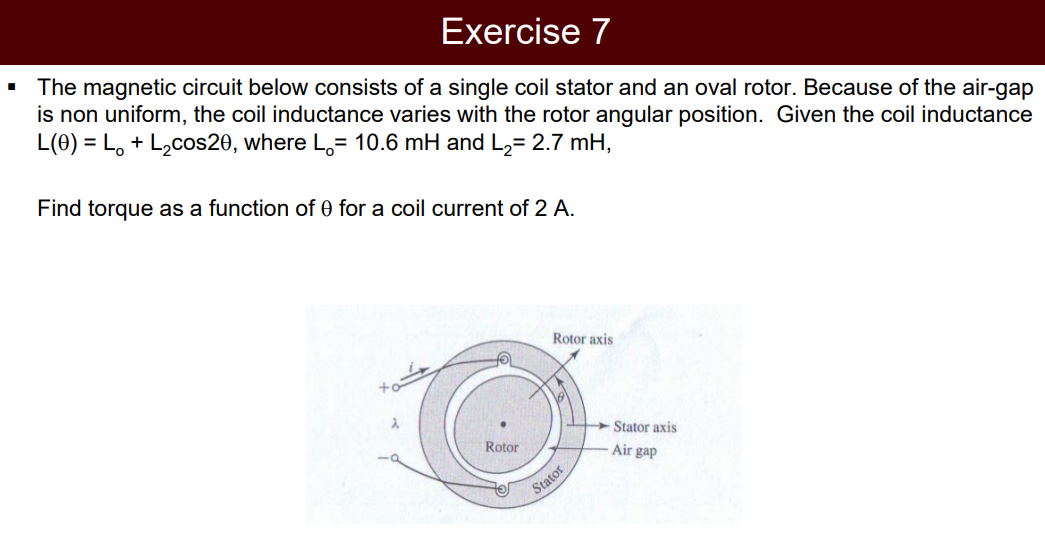

Lo = 10.6e-3;
L2 = 2.7e-3;

i = 2;

syms theta 
L = Lo + L2*cos(2*theta)

$$L = \frac{27\,\cos\left(2\,\theta \right)}{10000}+\frac{53}{5000}$$

T = i^2/2 * diff(L,theta)

$$T = -\frac{27\,\sin\left(2\,\theta \right)}{2500}$$